# **Dimensionality reduction on Ca2+ signal**

## 1.1 Use the default script to load the object

%% See script to change the default values across the demo scripts
STANDARD_INITIALIZATION()

	INFO : No change detected in time smoothing


lag_list =    -44   -42   -40   -38   -35   -33   -31   -29   -27   -24   -22   -20   -18   -15   -13   -11    -9    -7    -4    -2     0     2     4     7     9    11    13    15    18    20    22    24    27    29    31    33    35    38    40    42    44


lag_smoothing = 0


% note : the experiment loaded here has been preprocessed for peak detection and
% rescaling. If this is not the case, you need to do it.


## Rescale traces (enable median subtraction)

obj.find_events(); % you need to detect peaks first to enable rescaling, as it is done on the peaks

	INFO : Now detecting events with tree-wide pairwise correlation at least > 0.2 %
	INFO : 	Events detection is using PAIRWISE CORRELATION between all provided traces
			Epochs of correlated changes of activity across > 20 %% of the tree/pop will be considered as an event
			Events > 50 %% correlation will be considered as "global events". smaler correlations are local events

	WARNING : 	Maximal tree correlation is 94.2766%%. A values < 100%% indicates that either some sections belong to other neurons, or that the entire tree is never fully coactivated
				This function cannot distinguish between these two cases, but the value (max_corr_before_norm) will be set as the maximal possible correlation, and the globality index is proportional to this. This assumes that the entire tree CAN be correlated

	INFO : 290 events have been detected
	INFO : Peak times were extracted on the scaled avrage of all traces, but usi

obj.rescale_traces(); % rescale traces

	INFO : obj.binned_data.median traces were computed using rescaled signals


obj.rendering = 1;

# 1. PCA

## Example 1.1 : Run PCA

Default method : PCA on rescaled traces. using all timepoints, and auto estimating the number of components to get 90% od the explained variance

	WARNING : n_components was not specified. Number of factors was estimated as the number of PCA components required to explain 90 % of the variance (3) components)


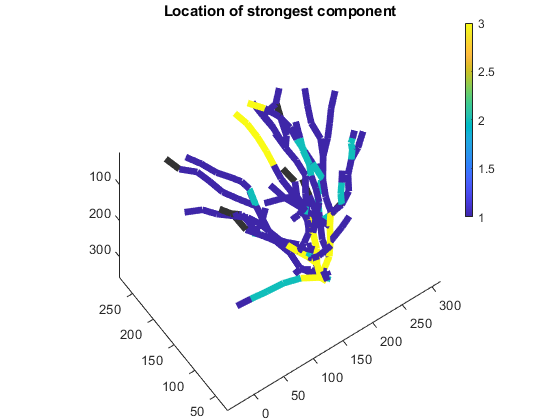

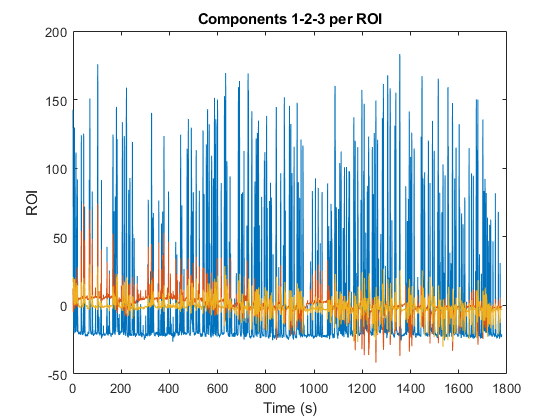

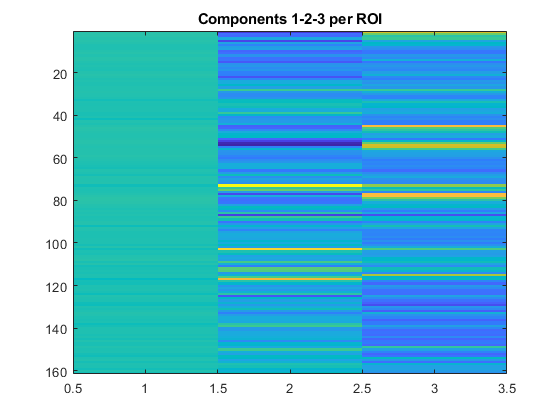

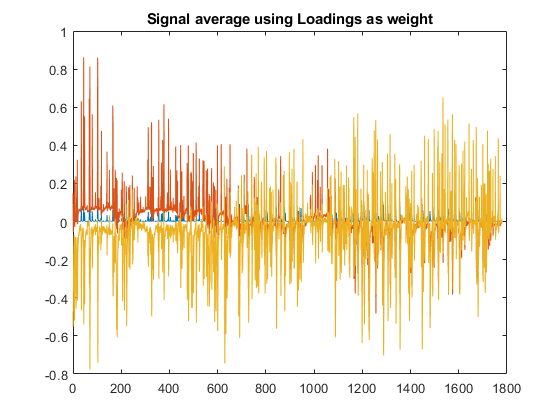

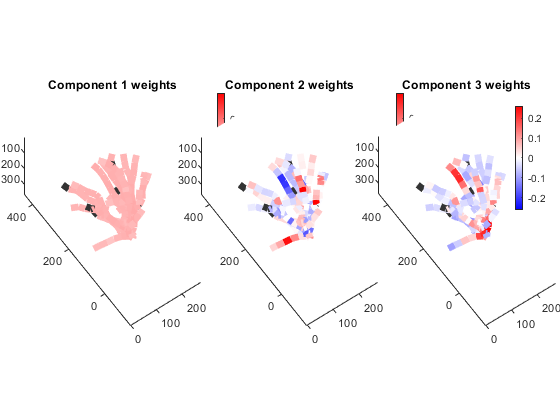

	INFO : 	Dimensionality reduction done using pca
			analysis done on 3 factors
			Data obtained from : original signal traces
			using the condition filter : manual_input



obj.get_dimensionality();

## Example 1.2 : Run PCA on rescaled traces and set number of components

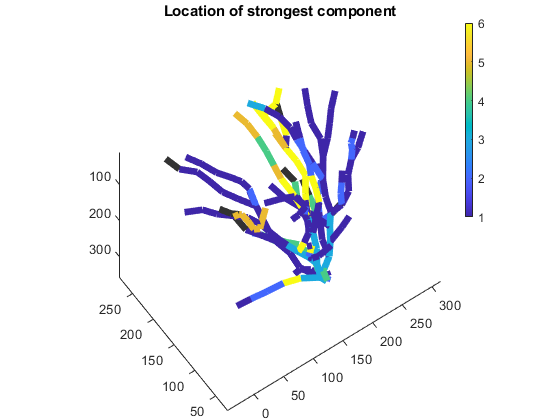

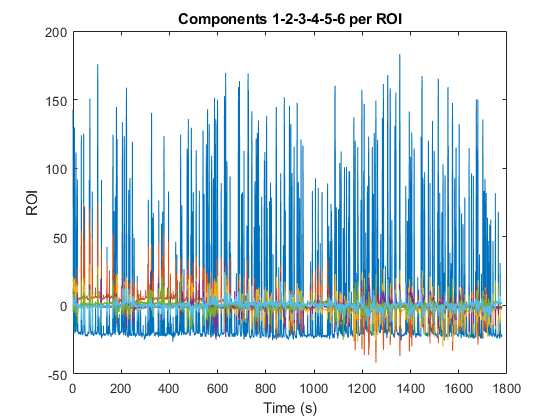

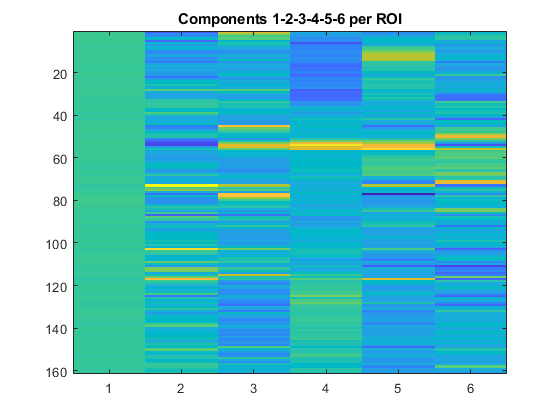

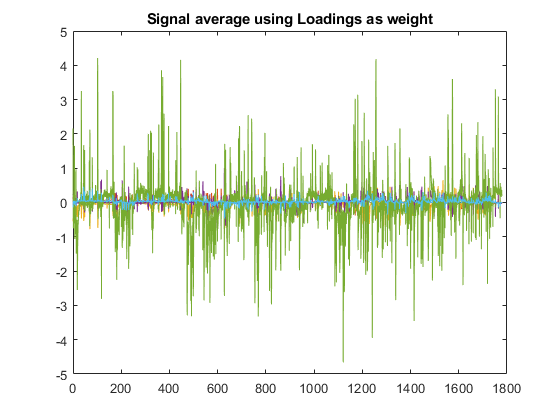

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 



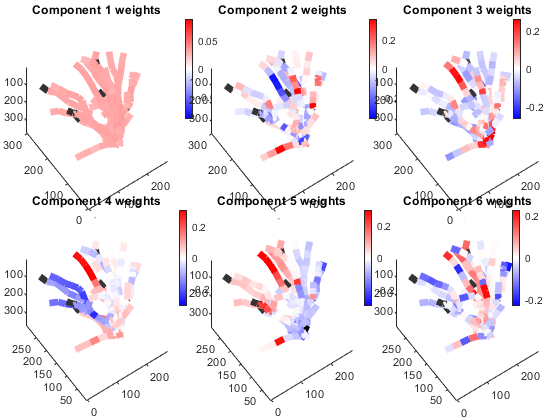

	INFO : 	Dimensionality reduction done using pca
			analysis done on 6 factors
			Data obtained from : original signal traces
			using the condition filter : manual_input



% Selecting first 6 components
obj.get_dimensionality(obj.rescaled_traces,'pca','',6); 

Note : obj.rescaled_trace and 'pca' are the default values, you don't actually have to set them

# 1. Timepoint Selection

The 4th input controls the timepoints that will be used. It can be the global events, some behavioural metrics or any arbitrary set of timepoints. See obj.get_tp_for_condition for more information

## Example 2.1 : Run PCA on rescaled peaks (not the whole traces)

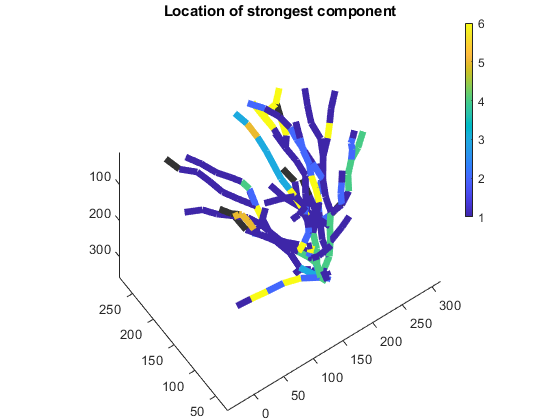

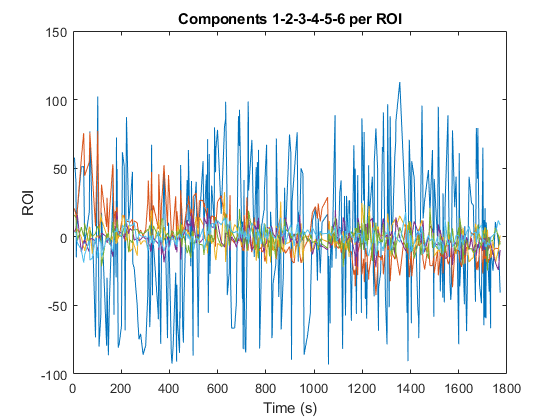

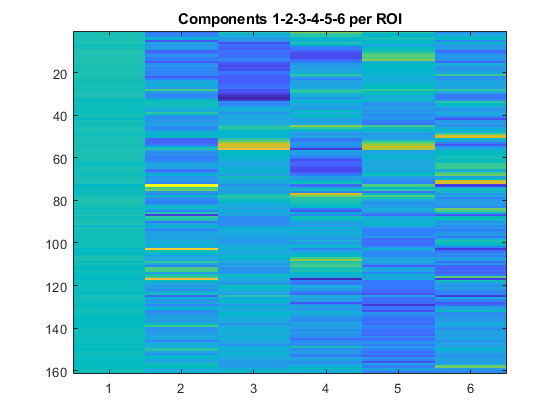

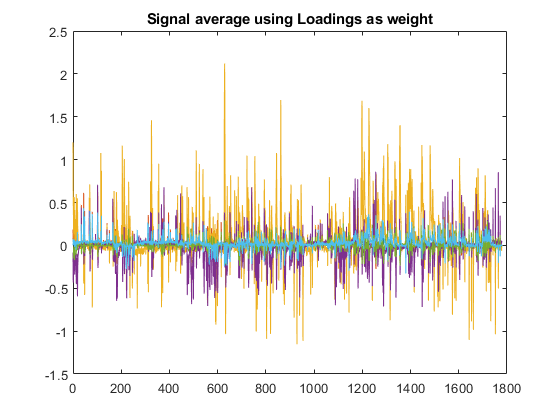

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 



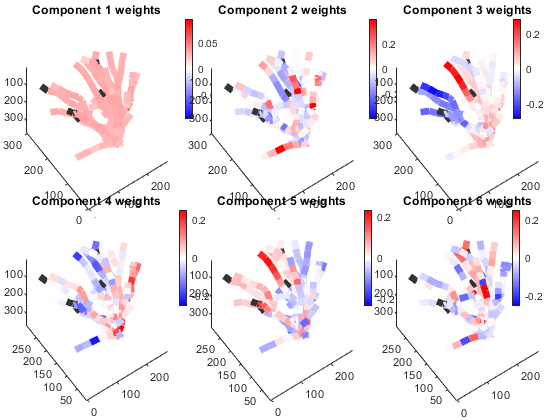

	INFO : 	Dimensionality reduction done using pca
			analysis done on 6 factors
			Data obtained from : original signal traces
			using the condition filter : peaks



obj.get_dimensionality(obj.rescaled_traces,'pca','peaks',6);

## Example 2.2 : Run PCA on median subtracted rescaled peaks 

Adding the subtracted flag wil lremove the signal median. This is likely to affect strongly the first Principal component in neurons presenting global events.

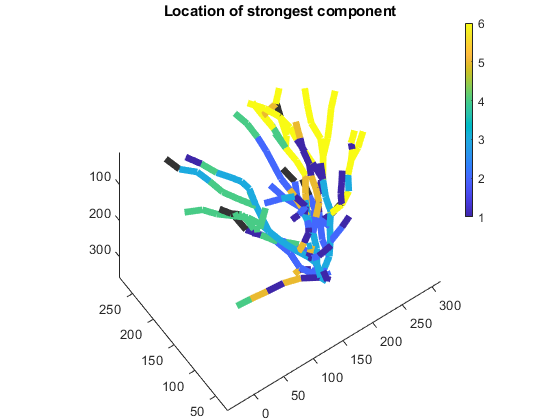

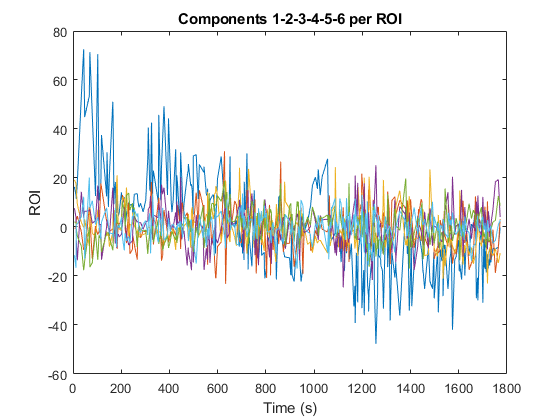

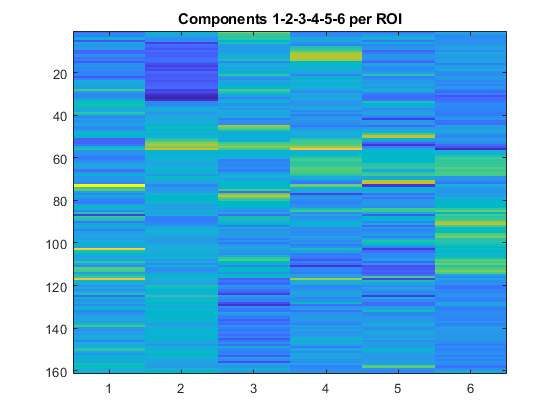

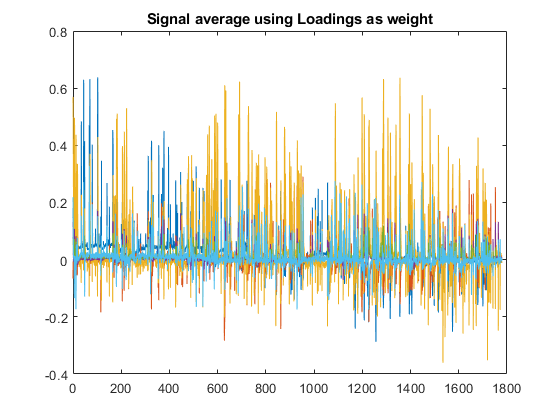

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 



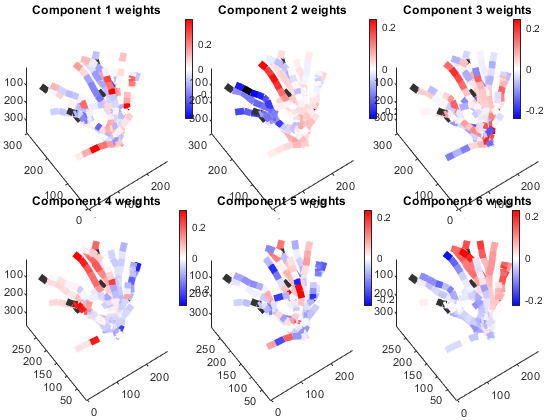

	INFO : 	Dimensionality reduction done using pca
			analysis done on 6 factors
			Data obtained from : median subtracted traces
			using the condition filter : peaks_subtracted



obj.get_dimensionality(obj.rescaled_traces,'pca','peaks_subtracted',6);

## Example 2.3 : Run PCA on median subtracted rescaled peaks during running only

You need to add the name of the behaviour to filter. Names can be obtained using obj.behaviour.types

	INFO : N bouts after extension / shrinkage and merging = 35


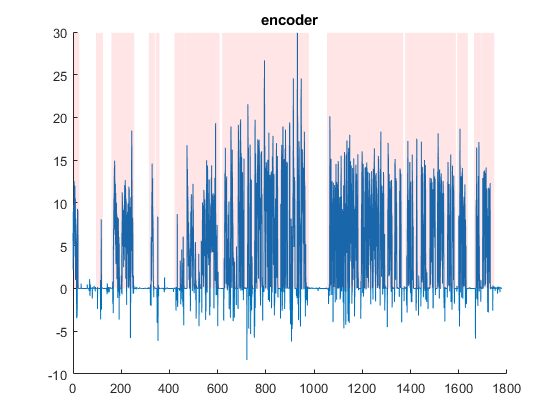

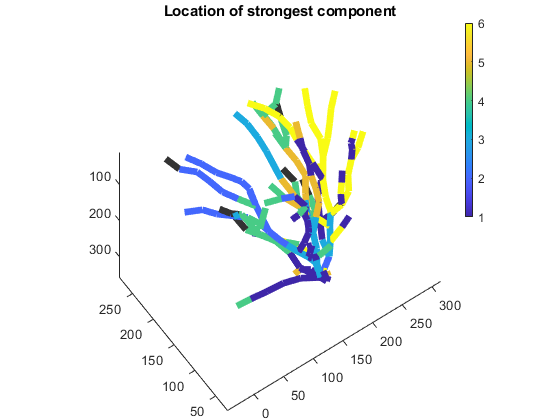

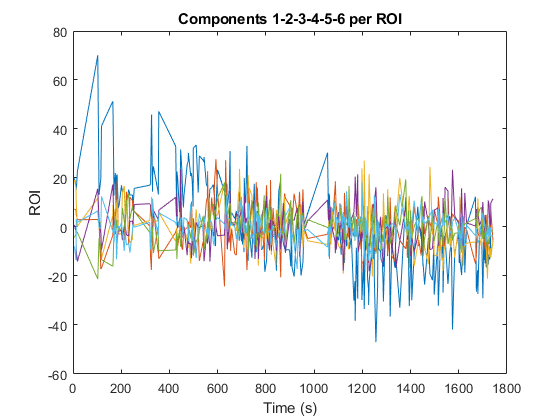

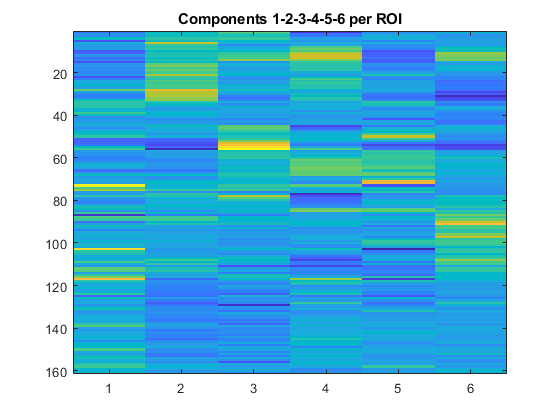

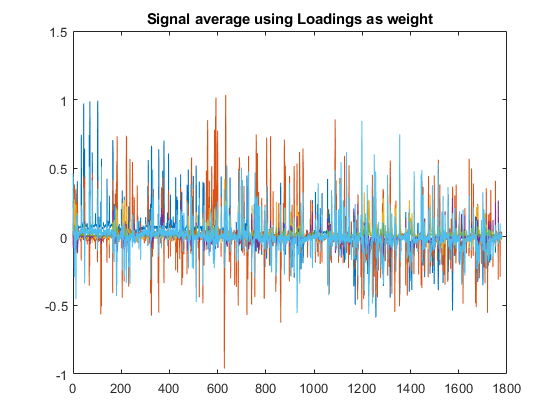

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 



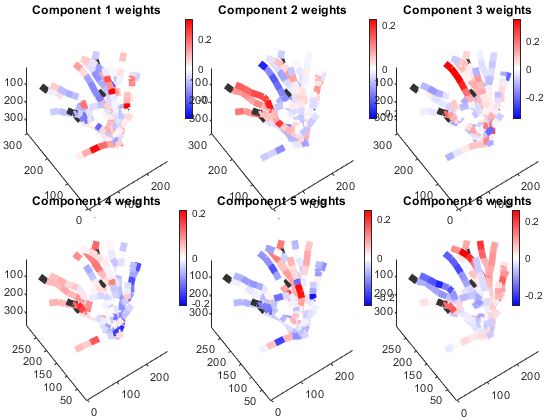

	INFO : 	Dimensionality reduction done using pca
			analysis done on 6 factors
			Data obtained from : median subtracted traces
			using the condition filter : peaks_subtracted_encoder



obj.get_dimensionality(obj.rescaled_traces,'pca','peaks_subtracted_encoder',6);

## Example 2.4 : Run PCA on median subtracted rescaled peaks while NOT running only

This correspond to the opposite set of timepoints compared to the previous section

	INFO : N bouts after extension / shrinkage and merging = 35


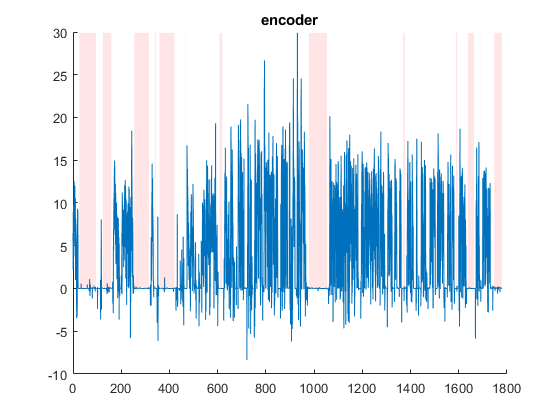

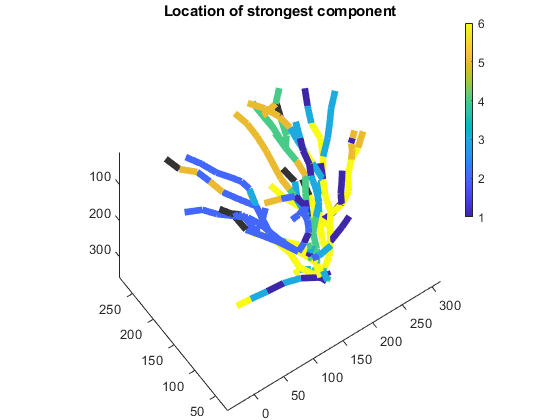

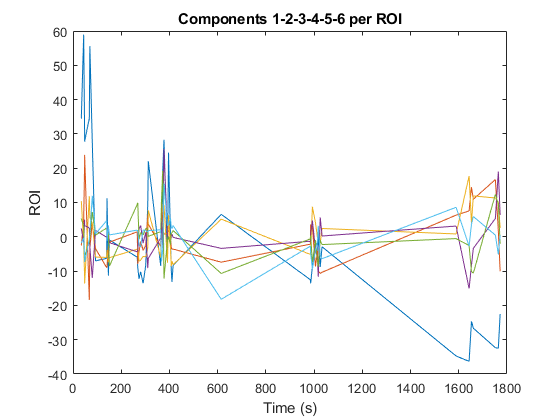

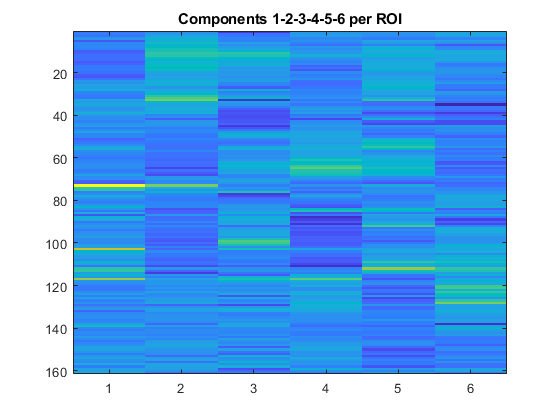

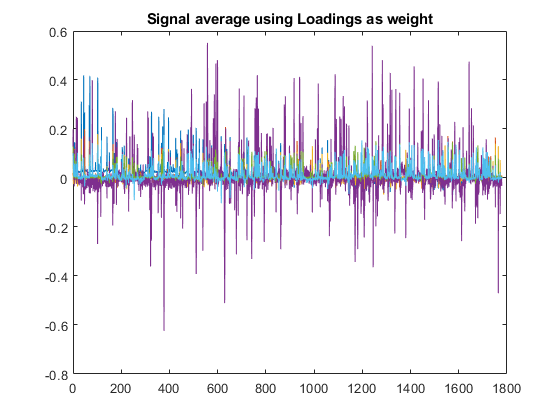

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 



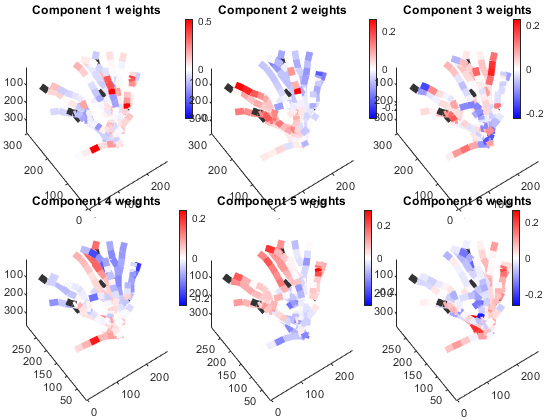

	INFO : 	Dimensionality reduction done using pca
			analysis done on 6 factors
			Data obtained from : median subtracted traces
			using the condition filter : peaks_subtracted_~encoder



obj.get_dimensionality(obj.rescaled_traces,'pca','peaks_subtracted_~encoder',6);

## Example 2.4 : Adjust behaviour smoothing and detrending

Smoothing can be very noisy. We'll match the smoothing to the calcium imaging smoothing. We'll also activate behaviour detrending to compensate for artefacts in Motion indices

Note that in this example, we use "whisker" which is not an exact match to one of the behaviour type. Consequently, all the matching values are selected.

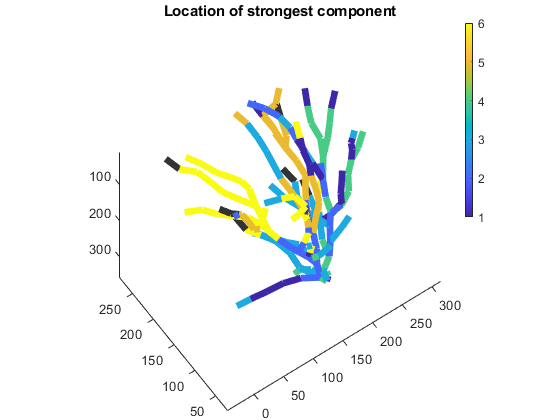

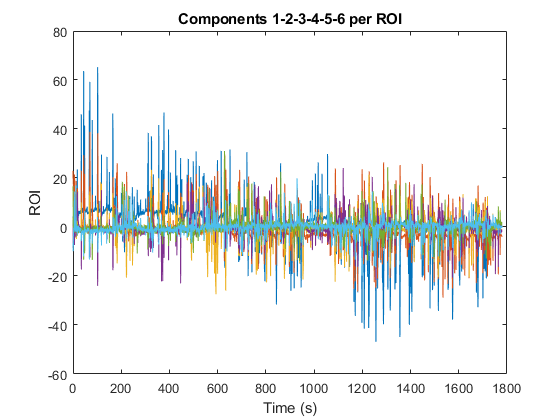

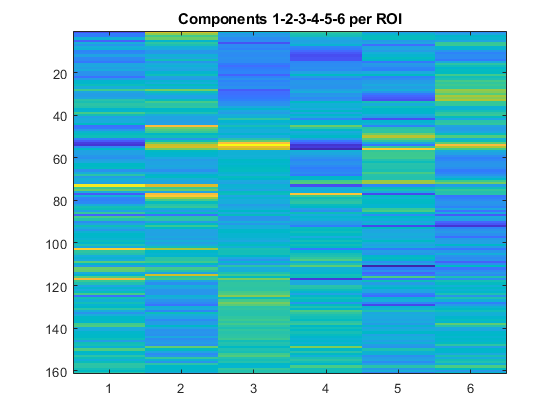

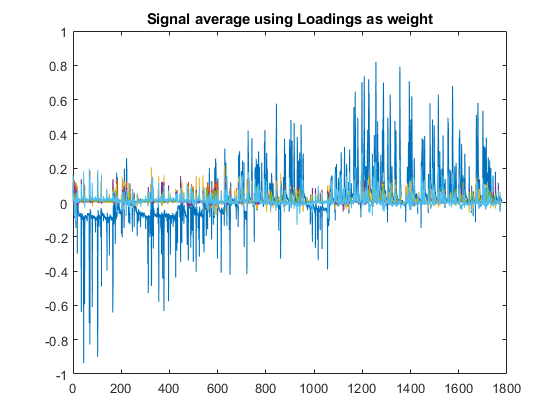

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 



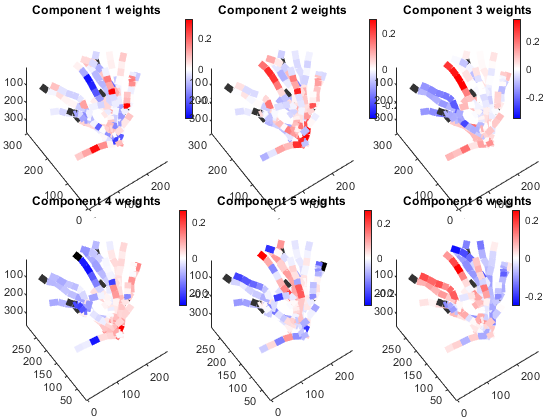

	INFO : 	Dimensionality reduction done using pca
			analysis done on 6 factors
			Data obtained from : median subtracted traces
			using the condition filter : peaks_subtracted_~BodyCam_L_whisker



obj.beh_smoothing = [-3,0];
obj.detrend_behaviour = 1;
obj.get_dimensionality(obj.rescaled_traces,'pca','peaks_subtracted_~BodyCam_L_whisker',6);

## Example 2.5 : Add a tail to behaviour timepoints

If you want to include movement onset for example, add a preceding windo to the "on" behaviour

	INFO : N bouts after extension / shrinkage and merging = 39


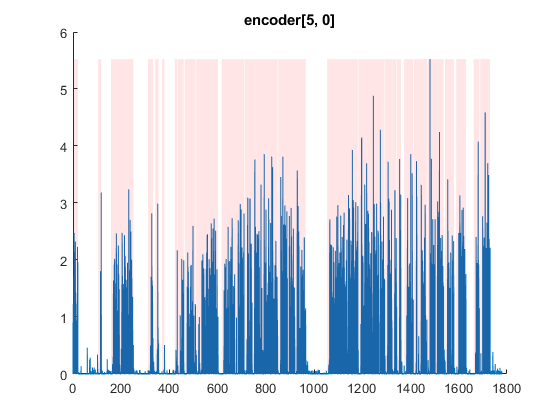

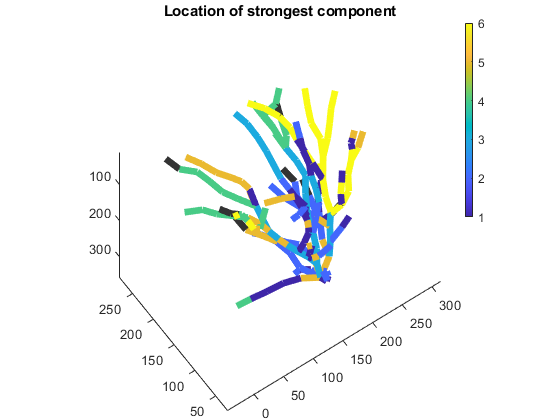

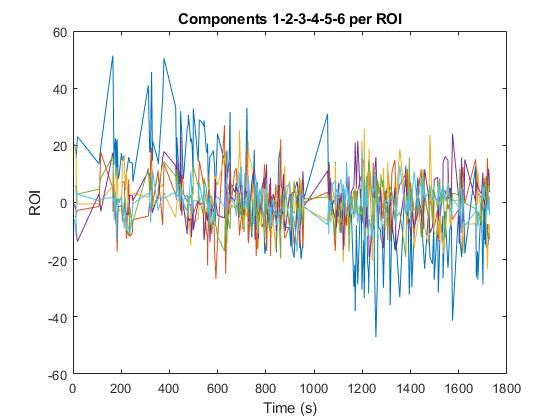

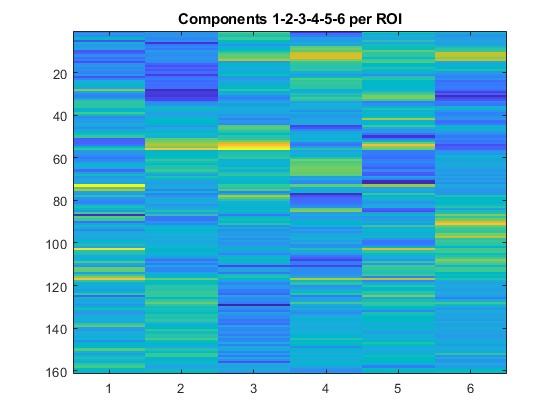

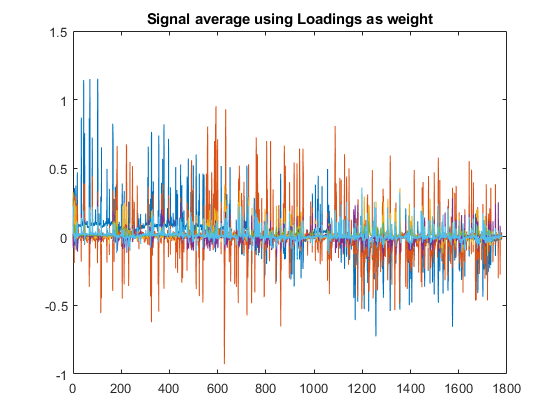

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 



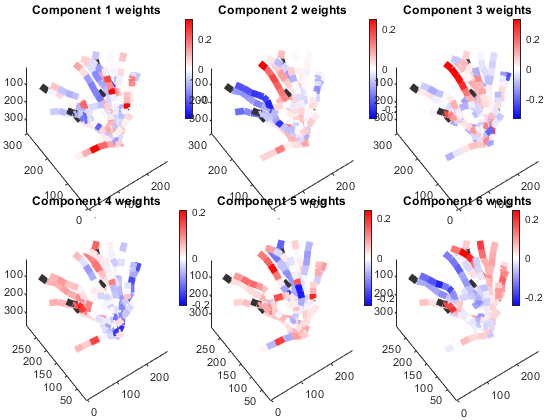

	INFO : 	Dimensionality reduction done using pca
			analysis done on 6 factors
			Data obtained from : median subtracted traces
			using the condition filter : peaks_subtracted_encoder[5, 0]



obj.get_dimensionality(obj.rescaled_traces,'pca','peaks_subtracted_encoder[5, 0]',6); % add 5 sec before the behaviour

# 3. Factor Analysis

## Example 3.1 : Run Factoran on rescaled traces and set number of components

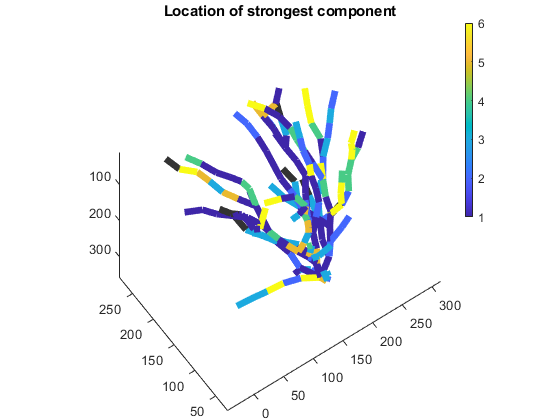

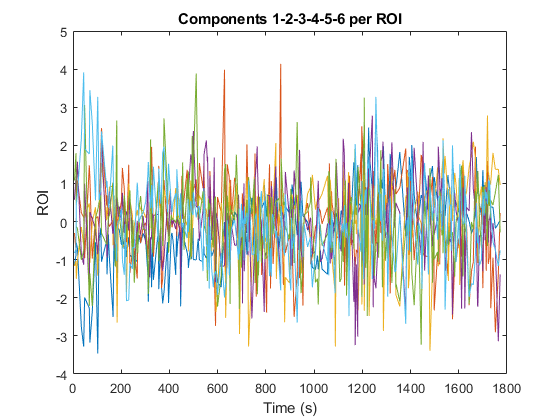

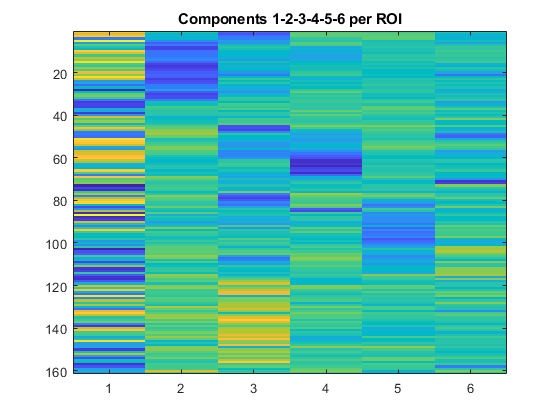

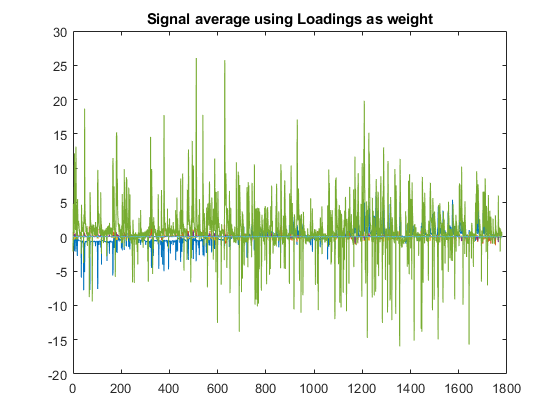

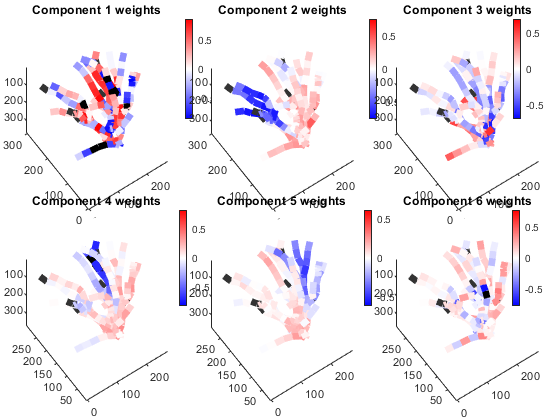

	INFO : 	Dimensionality reduction done using factoran
			analysis done on 6 factors
			Data obtained from : median subtracted traces
			using the condition filter : peaks_subtracted



% Selecting first 6 Factors
obj.get_dimensionality(obj.rescaled_traces,'factoran','peaks_subtracted',6);

Note : if you don't specify the number of factor, it is set as the number of PCA compnenents explaining 90% of the variance

# 4. NNMF

## Example 4.1 : Run NNMF on rescaled traces and set number of components

N_REPLICATES = 20

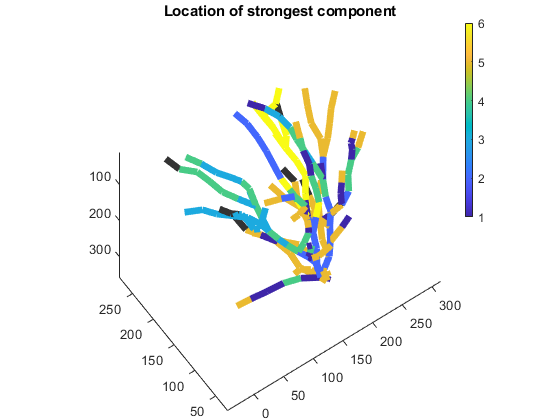

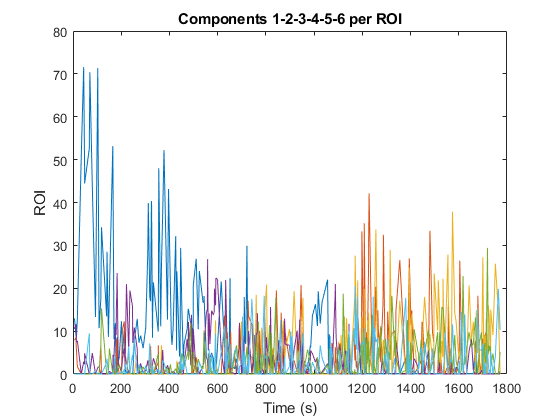

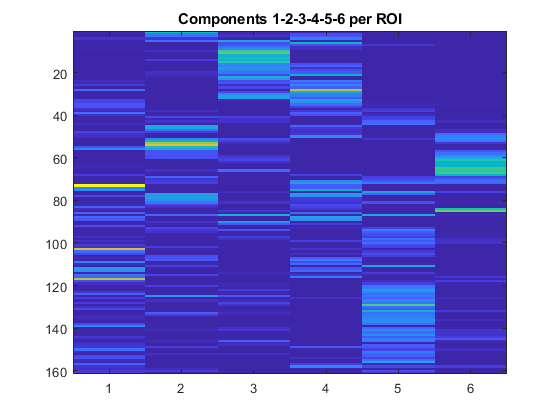

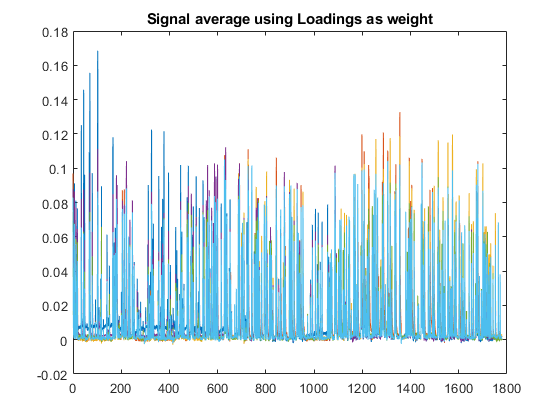

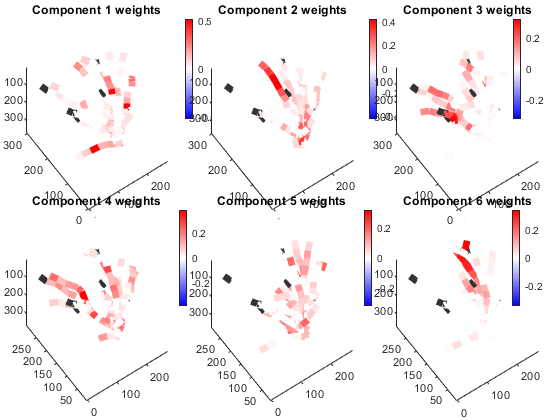

	INFO : 	Dimensionality reduction done using nnmf
			analysis done on 6 factors
			Data obtained from : median subtracted traces
			using the condition filter : peaks_subtracted



% Selecting first 6 Componenets
obj.get_dimensionality(obj.rescaled_traces,'nnmf','peaks_subtracted',6);

Note : NNMF will not capture negative modulation

# 5. PHATE

## Example 5.1 : Run PHATE on rescaled traces and set number of components

Doing PCA
PCA using random SVD
PCA took 0.0065068 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 161
First iteration: k = 100
Number of samples below the threshold from 1st iter: 161
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.025891 seconds
Make kernel row stochastic
Running PHATE without landmarking
Finding optimal t using VNE
VNE optimal t = 19


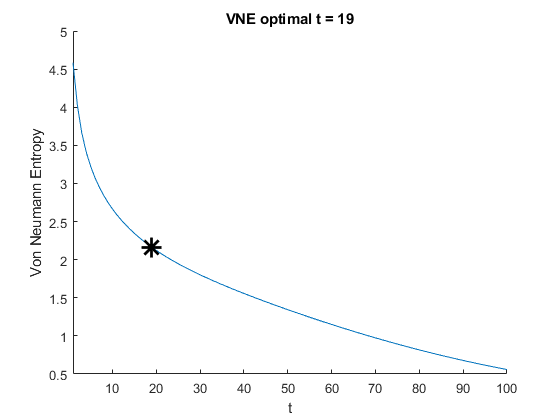

Diffusing operator
Diffusion took 0.0067173 seconds
Computing potential distances
using -log(P) potential distance
Computing potential distance took 0.0071003 seconds
Doing classical MDS
CMDS took 0.0023386 seconds
Doing metric MDS:

                     Stress          Norm of         Norm of     Line Search
   Iteration       Criterion        Gradient           Step       Iterations
  ---------------------------------------------------------------------------
           0        0.987647      0.00513206
           1        0.194886      0.00269735         94.4953              12
           2        0.150643      0.00342948         27.2216               9
           3       0.0847303      0.00396353         23.7239              10
           4       0.0510418      0.00265586         9.29797              10
           5       0.0320717      0.00304641         9.00525              10
           6       0.0229562      0.00287114         4.37345              21
           7       0.016263

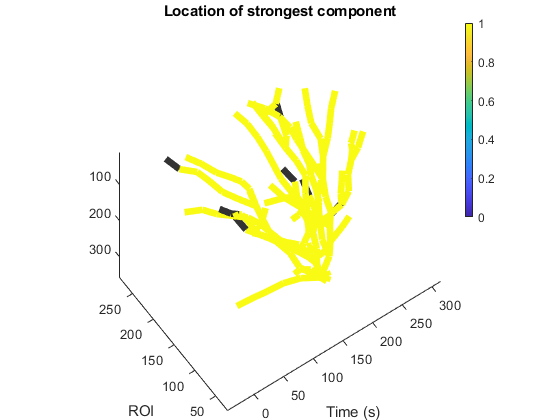

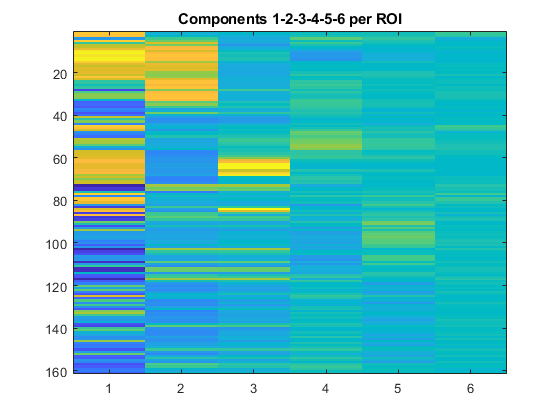

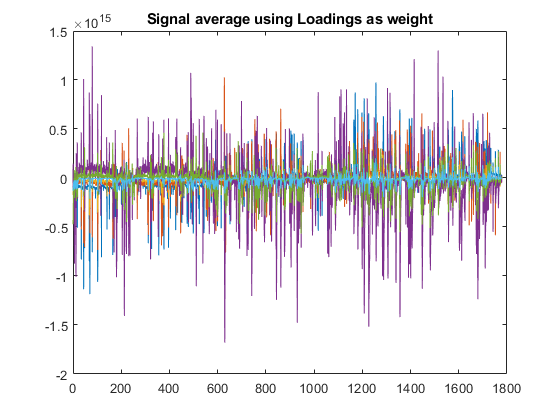

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 

	MAJOR WARNING : The number of color values is inferior to the number of colors in your colormap. Be careful if you used a cyclic colormap such as "lines", as different values may end up with the same color!! 



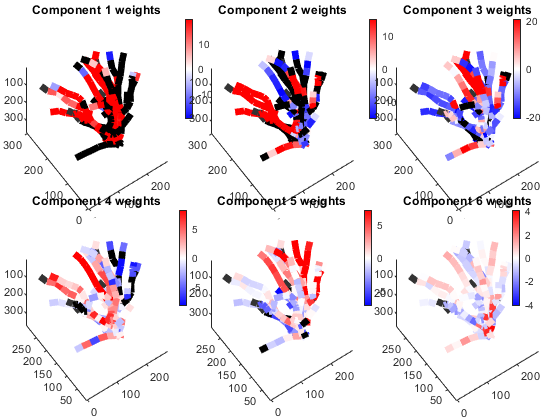

	INFO : 	Dimensionality reduction done using phate
			analysis done on 6 factors
			Data obtained from : median subtracted traces
			using the condition filter : peaks_subtracted



% Selecting first 6 Componenets
obj.get_dimensionality(obj.rescaled_traces,'phate','peaks_subtracted',6);

# 6. Clustering

## Example 6.1 : Run kmeans clustering

	INFO : Optimal number of clusters is 3
	INFO : Clustering done using KMEANS


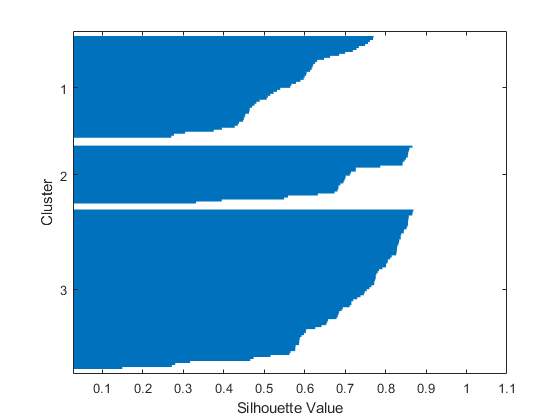

	INFO : Cluster number is sorted by number of ROI
	MAJOR WARNING : To fix - Tree aspect forced as simple 



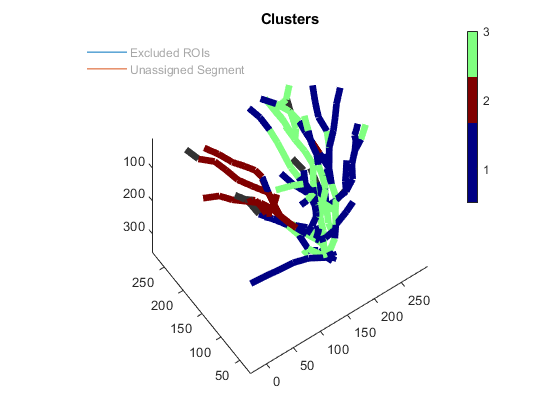

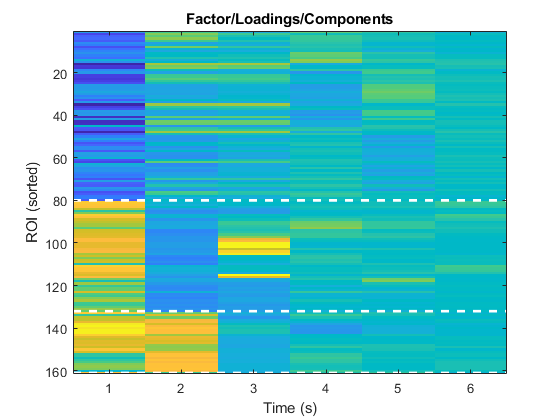

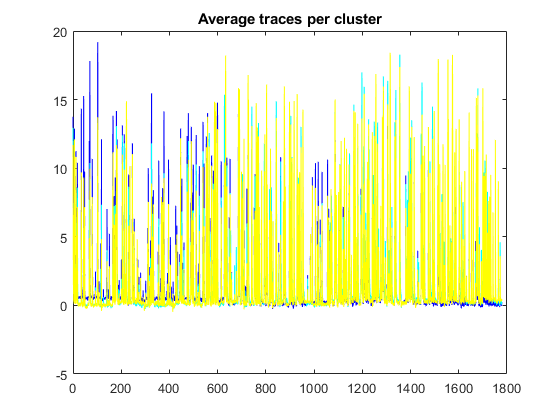

	INFO : 	Clustering of dimensionality-reduced data done using kmeans
			3 clusters have been identified



% Use kmeans with auto selection of the number of clusters
obj.cluster_factors('kmeans', []);

## Example 6.2 : Run kmeans clustering and force the number of clusters

	INFO : Clustering done using KMEANS


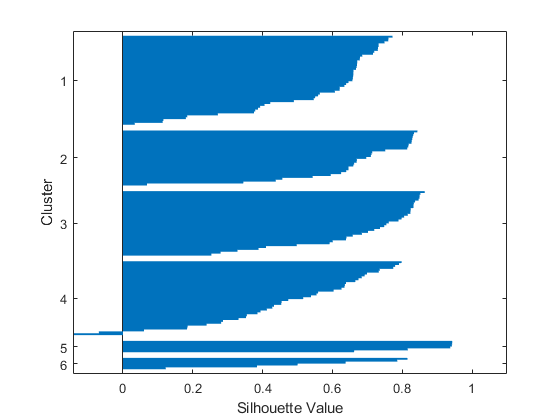

	INFO : Cluster number is sorted by number of ROI
	MAJOR WARNING : To fix - Tree aspect forced as simple 



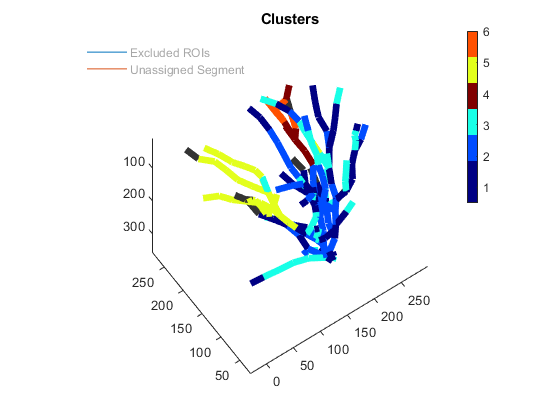

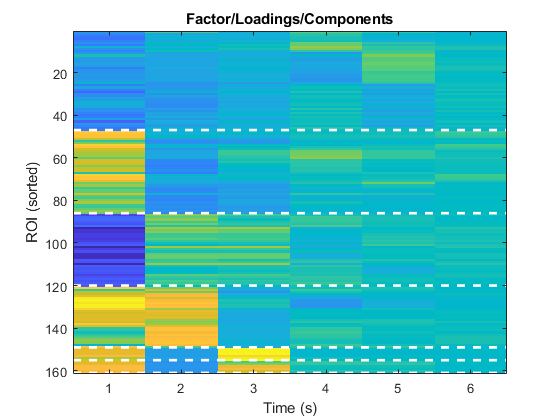

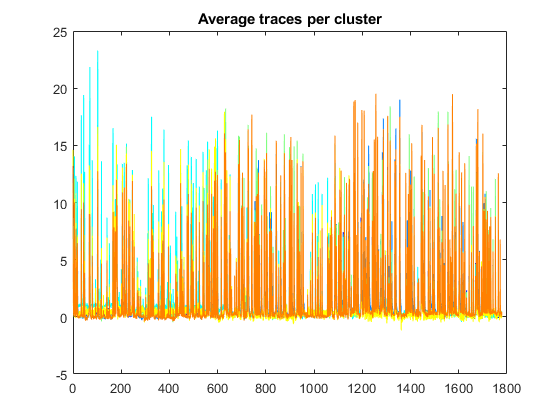

	INFO : 	Clustering of dimensionality-reduced data done using kmeans
			6 clusters have been identified



% Set 6 clusters
obj.cluster_factors('kmeans', 6);

## Example 6.3 : Run hierarchical clustering and force the number of clusters

	INFO : Optimal number of clusters is 4
	INFO : Clustering done using hierarchical clustering
	INFO : Cluster number is sorted by number of ROI
	MAJOR WARNING : To fix - Tree aspect forced as simple 



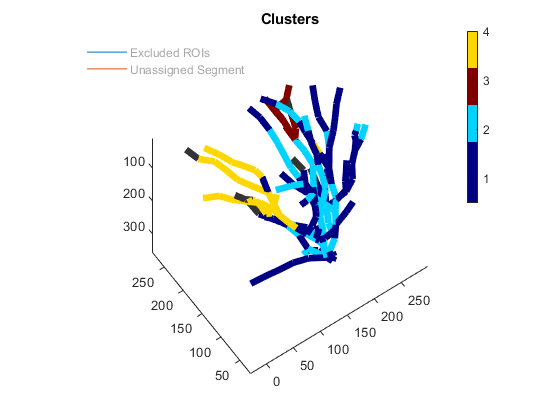

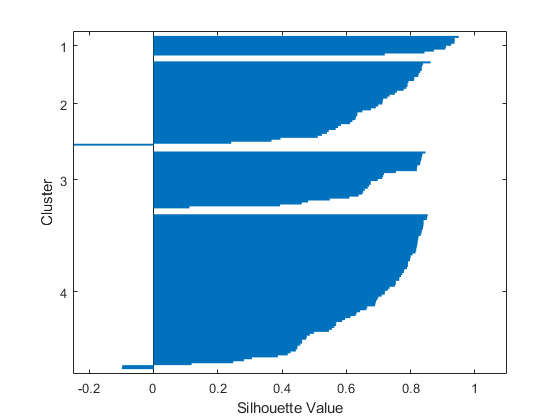

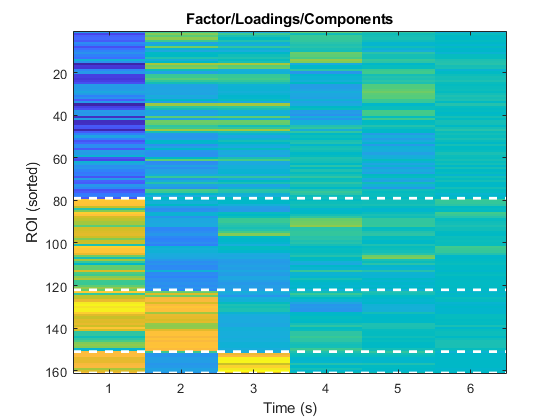

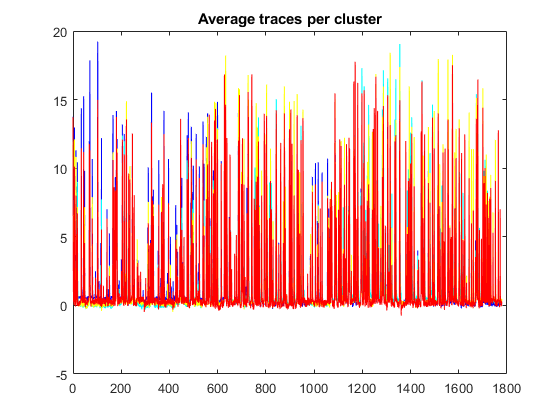

	INFO : 	Clustering of dimensionality-reduced data done using hierarchical
			4 clusters have been identified



% Use hierarchical with auto selection of the number of clusters
obj.cluster_factors('hierarchical', []);

## Example 6.4 : Run DBscan clustering with automated number of clusters

Optimal espilon s 4.2744
	INFO : Clustering done using dbscan
	INFO : Cluster number is sorted by number of ROI
	MAJOR WARNING : To fix - Tree aspect forced as simple 



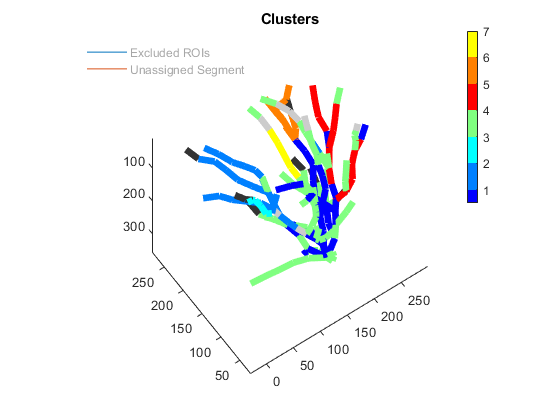

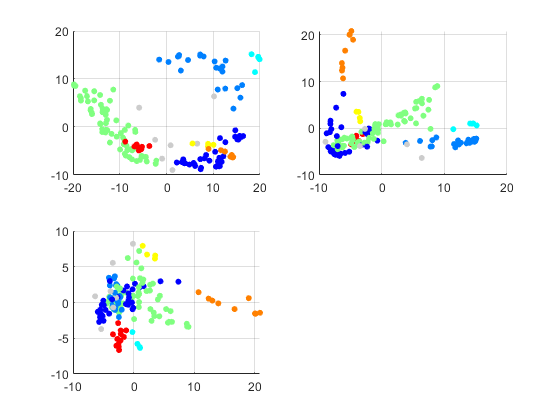

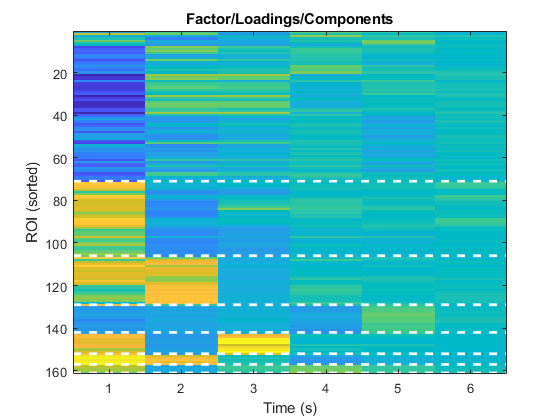

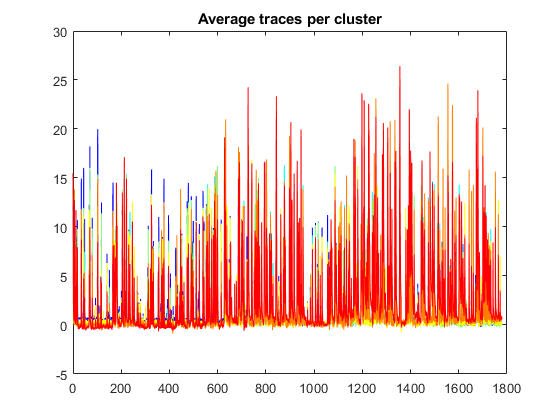

	INFO : 	Clustering of dimensionality-reduced data done using dbscan
			7 clusters have been identified



% Use DBscan with auto selection of the number of clusters
obj.cluster_factors('dbscan', []);

## Example 6.5 : Run DBscan clustering and set epsilon

	INFO : Clustering done using dbscan


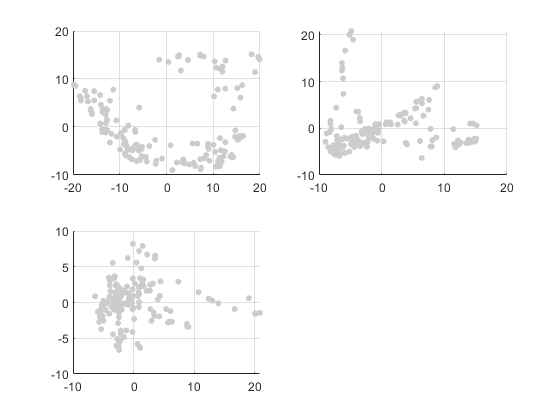

	MAJOR WARNING : To fix - Tree aspect forced as simple 



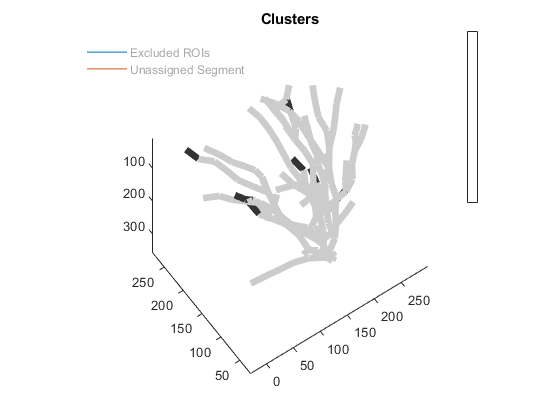

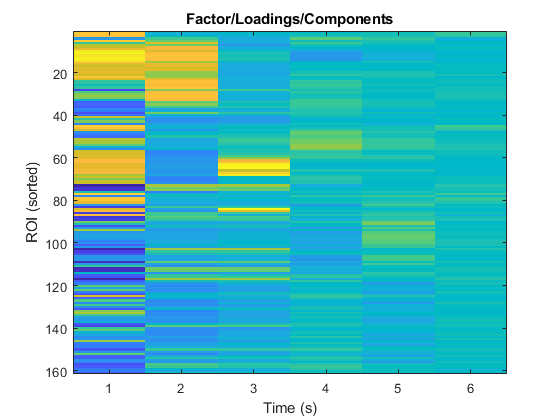

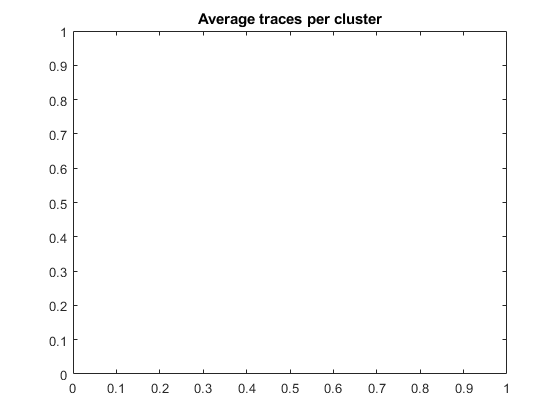

	INFO : 	Clustering of dimensionality-reduced data done using dbscan
			0 clusters have been identified



% The second input controls epsilon for dbscan methold
obj.cluster_factors('dbscan', 0.2);

## Example 6.5 : Run DBscan clustering and try to set the number of cluster manually

Witg this method, the algorithm will try to set the optimal epislon value allowing the specified number of clusters. Use a negative value to indicate you don't want epislon

	INFO : Clustering done using dbscan
	INFO : Cluster number is sorted by number of ROI
	MAJOR WARNING : To fix - Tree aspect forced as simple 



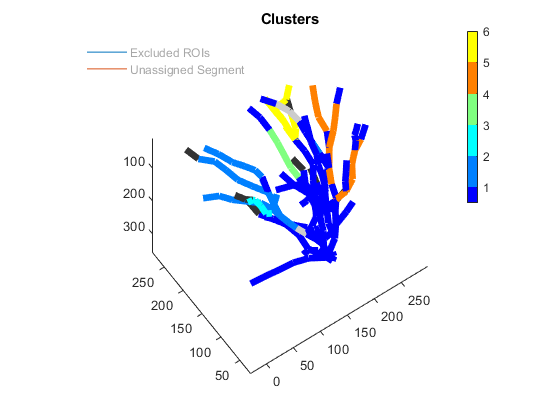

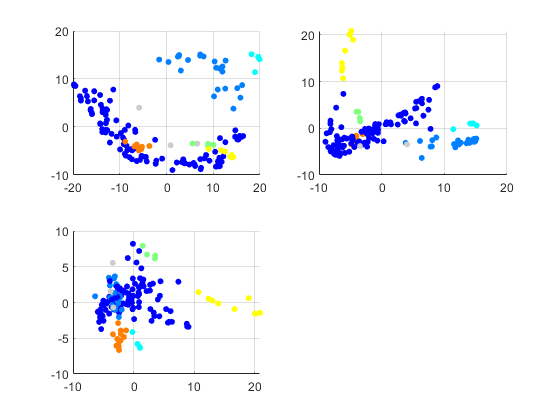

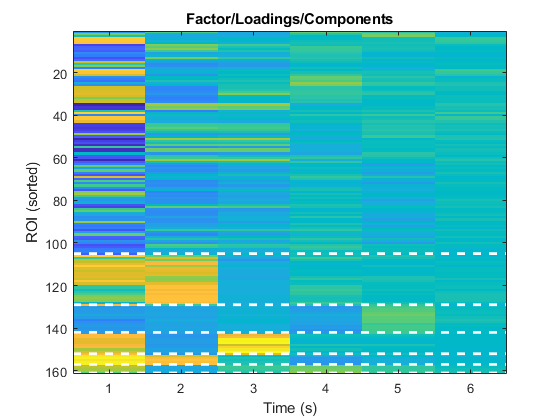

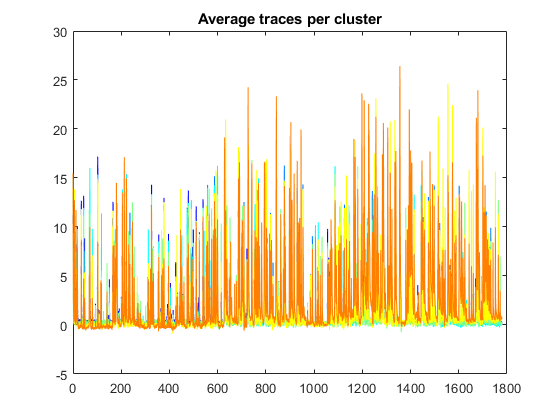

	INFO : 	Clustering of dimensionality-reduced data done using dbscan
			6 clusters have been identified



% The second input can control NCluster 
obj.cluster_factors('dbscan', -6);